# Mobile Robot Short project support

Use this preliminary code as the basis to develop the comming Short Project

## Run pose integration

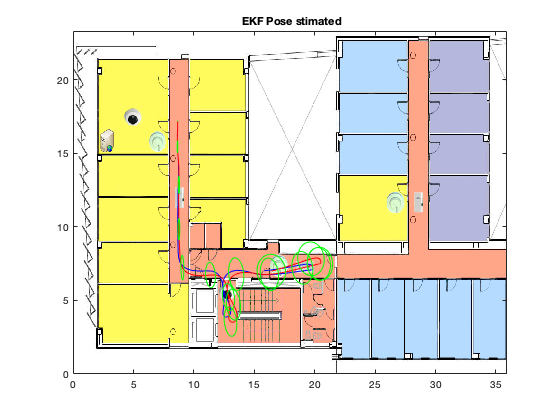

clear
close all
clf
sim("EKF_Pose_estimation.slx" )

## Plotting the enviroment and estimated trajectory

To add mor noise go to the Simulink model: EKF_Pose_estimation.slx

figure1=figure

figure1 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1001 919 560 420]
       Units: 'pixels'

  Show all properties

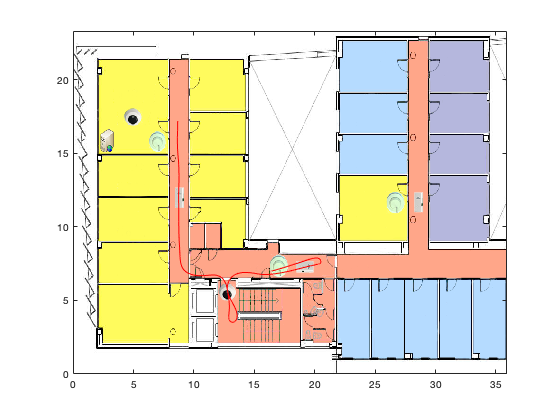

I=imread('Enviroment.png');
x_ima=[0 35.9];
y_ima=[23.31 0];
image(I,'XData',x_ima,'YData',y_ima);
axis xy
hold on
plot(Pose_est.Data(:,1),Pose_est.Data(:,2),'r')

## Land Marks

They are known. They can be extracter from laser data, there is easy algorithm like corner detection, etc ...

Lmk= [7.934 16.431 0 1;...
      9.583 16.431 0 1;...
      9.584 13.444 0 1;...
      9.584 10.461 0 1;...
      7.973 10.534 0 1;...
      7.934  7.547 0 1;...
      9.584  6.654 0 1;...
     13.001  6.525 0 1;...
     17.007  8.136 0 1];

### Plot Land Marks 

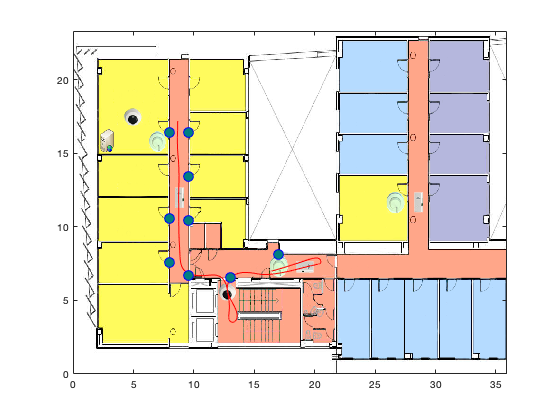

hold on
sz = 100;
s=scatter(Lmk(:,1),Lmk(:,2),sz);
s.LineWidth = 0.6;
s.MarkerEdgeColor = 'b';
s.MarkerFaceColor = [0 0.5 0.5];

## See an animation

In our system the computer is able to detect the landMark every 400ms

load('Laser_Data_CV__d_b.mat') % See the data
%%%%%%%%%%%%Robot shape %%%%%%%%%%%%
Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]';% The Robot icon is a triangle
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%Laser foot print %%%%%%%%
Laser_Range=3.9% meters

Laser_Range = 3.9000

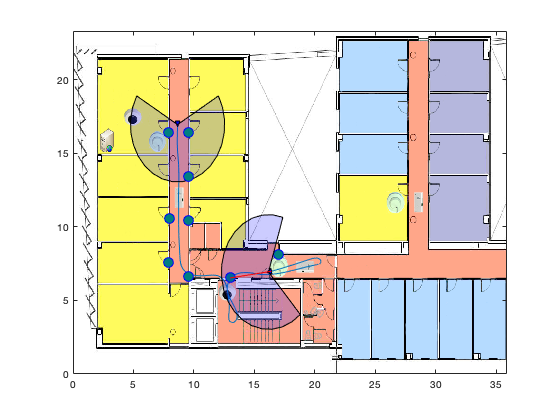

w=linspace(-30*pi/180,210*pi/180,20); %Laser foot print
s_x=Laser_Range*sin(w);s_y=Laser_Range*cos(w);
Lfp.v=[[s_x 0];[s_y 0]]';
Lfp.f= [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 1];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hold on
axis([0 35.9 0 23.31]);
Robot_tr=eye(4)*Robot;
hr=patch(Robot_tr(1,1), Robot_tr(2,1),'b');
hlfp=patch('Faces',Lfp.f,'Vertices',Lfp.v,'FaceColor','blue','FaceAlpha',.2);
hll=line([0 0.01],[0 0.01],'Color','red','LineStyle','-');
sz = 100; % to see thing biger
speed=5; % to speed up the animation
for i=1:3004 % Use the for loop to see a movie
k_m=mod(i,speed);
if k_m==0
delete (hr); % Deleting figures and laser lines
delete (hlfp);
delete (hll)
s=scatter(Lmk(:,1),Lmk(:,2),sz);
s.LineWidth = 0.6;
s.MarkerEdgeColor = 'b';
s.MarkerFaceColor = [0 0.5 0.5];
Robot_pose=transl(Pose_est.Data(i,1),Pose_est.Data(i,2),0)*trotz(Pose_est.Data(i,3));
Robot_tr=Robot_pose*Robot;% moving the robot 
Laser_fp=Robot_pose*transl(0.25,0,0)*[Lfp.v zeros(21,1) ones(21,1)]';
axis([0 35.9 0 23.31]);
hr=patch(Robot_tr(1,:), Robot_tr(2,:),'b');
hlfp=patch('Faces',Lfp.f,'Vertices',Laser_fp(1:2,:)','FaceColor','blue','FaceAlpha',.2);
Ls_lm_W=Robot_pose*[l_s_d(i,:).*cos(l_s_b(i,:));l_s_d(i,:).*sin(l_s_b(i,:)) ;zeros(1,9) ;ones(1,9)];
position=transl(Robot_pose);
hll=line([position(1) Ls_lm_W(1,1)...X's
          position(1) Ls_lm_W(1,2)...
          position(1) Ls_lm_W(1,3)...
          position(1) Ls_lm_W(1,4)...
          position(1) Ls_lm_W(1,5)...
          position(1) Ls_lm_W(1,6)...
          position(1) Ls_lm_W(1,7)...
          position(1) Ls_lm_W(1,8)...
          position(1) Ls_lm_W(1,9)],...
          [position(2) Ls_lm_W(2,1)...%Y's
          position(2) Ls_lm_W(2,2)...
          position(2) Ls_lm_W(2,3)...
          position(2) Ls_lm_W(2,4)...
          position(2) Ls_lm_W(2,5)...
          position(2) Ls_lm_W(2,6)...
          position(2) Ls_lm_W(2,7)...
          position(2) Ls_lm_W(2,8)...
          position(2) Ls_lm_W(2,9)],'Color','red','LineStyle','-');
pause(0.01);
end
end